clear

## Run other scripts

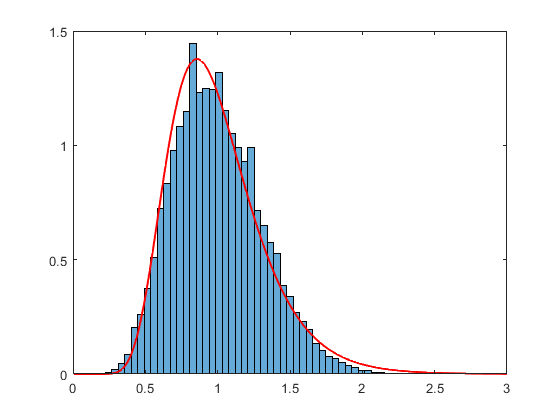

% DATA_TYPE = 'lowSI'; % or 'highSI'
DATA_TYPE = 'highSI';
MODEL = 'SVM';

Data_Proc_Import_predicted_data;

Parameters_delay;

Model_Atmospheric_turbulence;

ans = 1.0000


Model_AMP;

P_t = 2.0429

E_b_anal = 9.9999e+05

EE_anal = 4.8949e+08


% Model_Channel_state_thes;

if strcmp(DATA_TYPE, 'lowSI')
    load Workspace\Channel_state_thres_var\lowSI_fc=55.7.mat;
else
    load Workspace\Channel_state_thres_var\highSI_fc=55.7.mat;
end

% h_state_thres = h_state_thres(1:3:end);
% N_state = length(h_state_thres)-1;

Model_Channel_state_assignment;

Model_AMP_subopt_state;

P_t = 2.0176

rate_anal = 9.6813e+08

EE_anal = 4.7983e+08

x_arr = [0, 1, 3, 5, 7];     % n_delay array
% x_arr = 0;

## Compute AVR Power for different $n_{delay$

for j = 1:length(x_arr)

-         Delayed CSI - AMP scheme

    n_delay = x_arr(j);

    Model_AMP_delay;
    
    count_AMP_delay(j) = count;
    
    EL_AMP_delay(j) = energy_loss;
    
    EE_AMP_delay(j) = EE_delay;
    

-         Delayed CSI - Sub-optimal AMP scheme

    Model_AMP_subopt_state_delay;

    count_subopt_delay(j) = count;
    
    EL_subopt_delay(j) = energy_loss;
    
    EE_subopt_delay(j) = EE_delay;

-         Predicted CSI - Sub-optimal AMP scheme

    if n_delay == 0
    
        % Model_AMP_predicted;
        Model_AMP_subopt_state_predicted;

        count_subopt_predicted = count;

        EL_subopt_predicted = energy_loss;
        
        EE_subopt_predicted = EE_predicted;

    end
end

EE_delay = 4.9730e+08

energy_loss = 0

energy_loss = 0

EE_delay = 4.8762e+08

energy_loss = 6.7918e-05

EE_predicted = 4.7114e+08

EE_delay = 2.5799e+08

energy_loss = 9.7529e-04

energy_loss = 5.2299e-04

EE_delay = 3.6117e+08

EE_delay = 2.3879e+08

energy_loss = 0.0010

energy_loss = 7.8957e-04

EE_delay = 2.8083e+08

EE_delay = 2.3057e+08

energy_loss = 0.0011

energy_loss = 8.4212e-04

EE_delay = 2.5761e+08

EE_delay = 2.2531e+08

energy_loss = 0.0011

energy_loss = 8.9587e-04

EE_delay = 2.4611e+08

# Plot the figures

## Set global configurations

set(groot, 'defaultLineMarkerSize', 25);
set(groot, 'DefaultLineLineWidth', 2);
set(groot, 'defaultAxesFontName', 'TimesNewRoman');
set(groot, 'defaultTextFontName', 'TimesNewRoman');
set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultTextFontSize', 12);

# Low SI data type

if strcmp(DATA_TYPE, 'lowSI')

# Figures: AMP vs Sub-optimal AMP schemes

## Fig: Probability that $BER_{inst$ exceeds $BER_{tar$

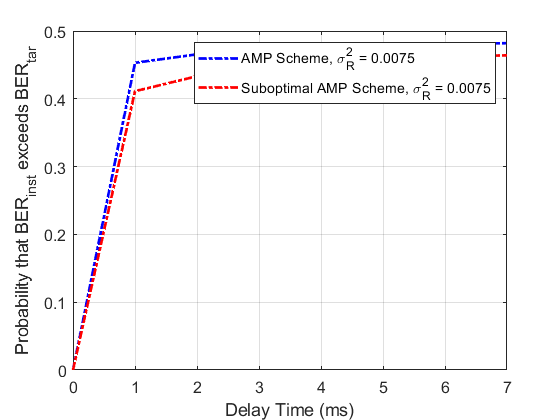

    plot(x_arr, count_AMP_delay/N_sample, '-.b', "DisplayName", 'AMP Scheme, \sigma_R^2 = 0.0075')
    hold on
    
    plot(x_arr, count_subopt_delay/N_sample, '-.r', "DisplayName", 'Suboptimal AMP Scheme, \sigma_R^2 = 0.0075')
    hold off
    
    xlabel('Delay Time (ms)')
    ylabel('Probability that BER_{inst} exceeds BER_{tar}')
    legend()
    grid on

## Fig: Energy loss

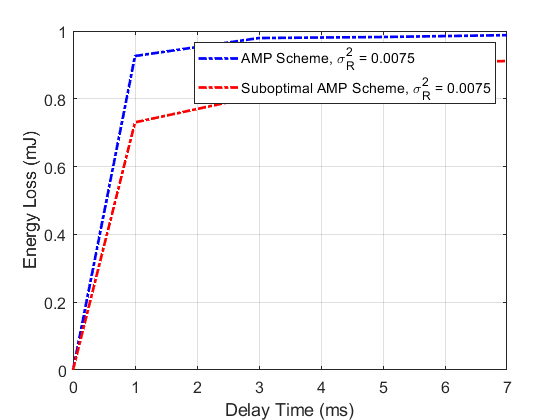

    plot(x_arr, EL_AMP_delay .* 1e3, '-.b', "DisplayName", 'AMP Scheme, \sigma_R^2 = 0.0075')
    hold on
    
    plot(x_arr, EL_subopt_delay .* 1e3, '-.r', "DisplayName", 'Suboptimal AMP Scheme, \sigma_R^2 = 0.0075')
    hold off
    
    xlabel('Delay Time (ms)')
    ylabel('Energy Loss (mJ)')
    legend()
    grid on

## Fig: Energy Efficiency

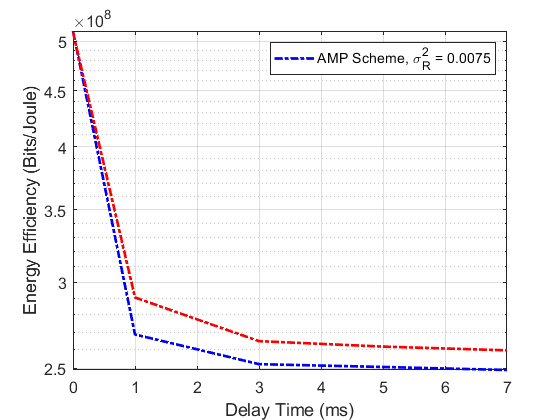

    semilogy(x_arr, EE_AMP_delay, '-.b', "DisplayName", 'AMP Scheme, \sigma_R^2 = 0.0075')
    hold on
    
    semilogy(x_arr, EE_subopt_delay, '-.r', "DisplayName", 'Suboptimal AMP Scheme, \sigma_R^2 = 0.0075', 'HandleVisibility','off')
    hold off
    
    xlabel('Delay Time (ms)')
    ylabel('Energy Efficiency (Bits/Joule)')
    legend()
    grid on

# Figure: Perfect Channel vs Delayed Channel

## Fig: Probability that $BER_{inst$ exceeds $BER_{tar$

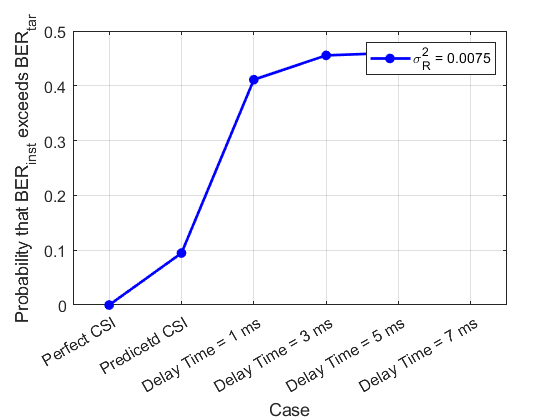

    x_axis = categorical(["Perfect CSI", "Predicetd CSI", "Delay Time = 1 ms", "Delay Time = 3 ms", "Delay Time = 5 ms", "Delay Time = 7 ms"]);
    
    x_axis = reordercats(x_axis, ["Perfect CSI", "Predicetd CSI", "Delay Time = 1 ms", "Delay Time = 3 ms", "Delay Time = 5 ms", "Delay Time = 7 ms"]);
    
    y_axis = [count_subopt_delay(1), count_subopt_predicted, count_subopt_delay(2:end)] ./ N_sample;
    
    plot(x_axis, y_axis, '.-b', "DisplayName", '\sigma_R^2 = 0.0075')
    
    xlabel('Case')
    ylabel('Probability that BER_{inst} exceeds BER_{tar}')
    legend()
    grid on

## Fig: Energy loss

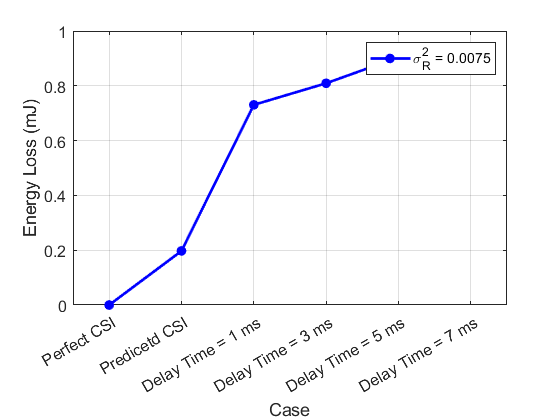

    y_axis = [EL_subopt_delay(1) EL_subopt_predicted EL_subopt_delay(2:end)] .* 1e3;
       
    plot(x_axis, y_axis, '.-b', "DisplayName", '\sigma_R^2 = 0.0075')
    
    xlabel('Case')
    ylabel('Energy Loss (mJ)')
    legend()
    grid on

## Fig: Energy Efficiency

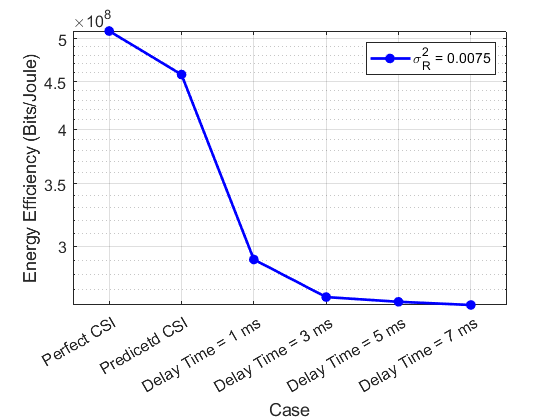

    y_axis = [EE_subopt_delay(1) EE_subopt_predicted EE_subopt_delay(2:end)];
        
    semilogy(x_axis, y_axis, '.-b', "DisplayName", '\sigma_R^2 = 0.0075')
    
    xlabel('Case')
    ylabel('Energy Efficiency (Bits/Joule)')
    legend()
    grid on

end

# High SI data type

if strcmp(DATA_TYPE, 'highSI')

# Figures: AMP vs Sub-optimal AMP schemes

## Fig: Probability that $BER_{inst$ exceeds $BER_{tar$

    plot(x_arr, count_AMP_delay/N_sample, '.-', "DisplayName", 'AMP Scheme, \sigma_R^2 = 0.1020')
    hold on
    
    plot(x_arr, count_subopt_delay/N_sample, '.-', "DisplayName", 'Suboptimal AMP Scheme, \sigma_R^2 = 0.1020')
    hold off
    
    xlabel('Delay Time (ms)')
    ylabel('Probability that BER_{inst} exceeds BER_{tar}')
    legend()
    grid on

## Fig: Energy loss

    plot(x_arr, EL_AMP_delay .* 1e3, '.-', "DisplayName", 'AMP Scheme, \sigma_R^2 = 0.1020')
    hold on
    
    plot(x_arr, EL_subopt_delay .* 1e3, '.-', "DisplayName", 'Suboptimal AMP Scheme, \sigma_R^2 = 0.1020')
    hold off
    
    xlabel('Delay Time (ms)')
    ylabel('Energy Loss (mJ)')
    legend()
    grid on

## Fig: Energy Efficiency

    semilogy(x_arr, EE_AMP_delay, '-o', "DisplayName", 'AMP Scheme, \sigma_R^2 = 0.1020')
    hold on
    
    semilogy(x_arr, EE_subopt_delay, '-o', "DisplayName", 'Suboptimal AMP Scheme, \sigma_R^2 = 0.1020', 'HandleVisibility','off')
    hold off
    
    xlabel('Delay Time (ms)')
    ylabel('Energy Efficiency (Bits/Joule)')
    legend()
    grid on

# Figure: Perfect Channel vs Delayed Channel

## Fig: Probability that $BER_{inst$ exceeds $BER_{tar$

    x_axis = categorical(["Perfect CSI", "Predicetd CSI", "Delay Time = 1 ms", "Delay Time = 3 ms", "Delay Time = 5 ms", "Delay Time = 7 ms"]);
    
    x_axis = reordercats(x_axis, ["Perfect CSI", "Predicetd CSI", "Delay Time = 1 ms", "Delay Time = 3 ms", "Delay Time = 5 ms", "Delay Time = 7 ms"]);
    
    y_axis = [count_subopt_delay(1), count_subopt_predicted, count_subopt_delay(2:end)] ./ N_sample;
    
    plot(x_axis, y_axis, '.-r', "DisplayName", '\sigma_R^2 = 0.1020')
        
    xlabel('Case')
    ylabel('Probability that BER_{inst} exceeds BER_{tar}')
    legend()
    grid on

## Fig: Energy loss

    y_axis = [EL_subopt_delay(1) EL_subopt_predicted EL_subopt_delay(2:end)] .* 1e3;
    
    plot(x_axis, y_axis, '.-r', "DisplayName", '\sigma_R^2 = 0.1020')
    
    xlabel('Case')
    ylabel('Energy Loss (mJ)')
    legend()
    grid on

## Fig: Energy Efficiency

    y_axis = [EE_subopt_delay(1) EE_subopt_predicted EE_subopt_delay(2:end)];
    
    semilogy(x_axis, y_axis, '.-r', "DisplayName", '\sigma_R^2 = 0.1020')
    
    xlabel('Case')
    ylabel('Energy Efficiency (Bits/Joule)')
    legend()
    grid on

end